# Proprioception-based movement goals support imitation and are disrupted in apraxia - Isaacs, Buxbaum, and Wong (2021)

All data from [link](https://osf.io/gvpy8/?view_only=24c4dea37dec4c5a858a5e54a3ccb113) in paper to lab OSF page. 

clear; clc;
code_folder = '/Users/duncan/Documents/GitHub/Recreate-Papers/Wong_VPImitation';
cd(code_folder)

## Load

dirs = {code_folder, append(code_folder, '/prop_test'), append(code_folder, '/Visual_Control_Task_data')};
for d = 1:length(dirs)
    cd(dirs{d}); 
    mats = dir('*.mat');
    for i = 1:length(mats)
        load(mats(i).name);
    end
end
cd(code_folder)

## Explore

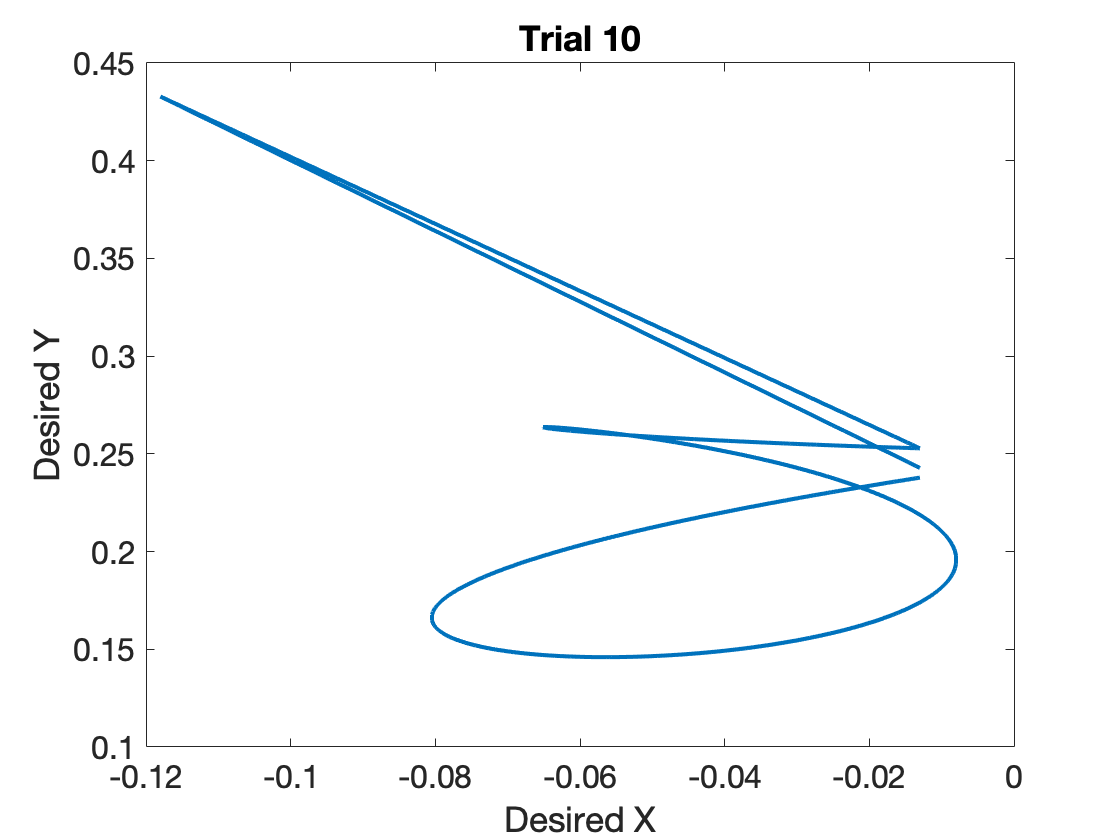

D = 10;
figure();
plot(c3d(D).desiredX, c3d(D).desiredY, 'linewidth', 2)
xlabel('Desired X'); ylabel('Desired Y'); title(sprintf('Trial %d', D))
set(gca(), 'fontsize', 16)